Name: Omar Quishawi

ID:20200124

Question 1

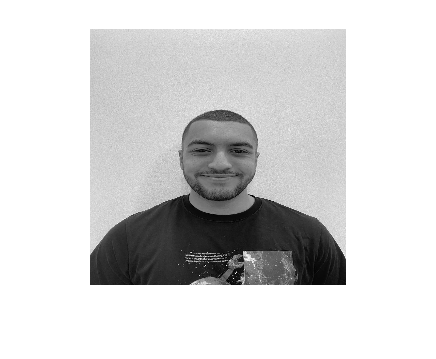

mypath = "megray.tif";

[me,melut] = imread(mypath);
figure;
subplot(1,1,1);
imshow(me);

me_info = imfinfo(mypath);
me_info

me_info = struct with fields:
                     Filename: 'C:\Users\LENOVO\Desktop\PSUT\1st sem - Y4\Digital Image processing\images\megray.tif'
                  FileModDate: '13-Nov-2023 10:39:17'
                     FileSize: 66250
                       Format: 'tif'
                FormatVersion: []
                        Width: 256
                       Height: 256
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 8274 16534 24799 33059 41326 49532 57792]
              SamplesPerPixel: 1
                 RowsPerStrip: 32
              StripByteCounts: [8266 8260 8265 8260 8267 8206 8260 8204]
                  XResolution: 72
                  YResolution: 72
               R

Question 2

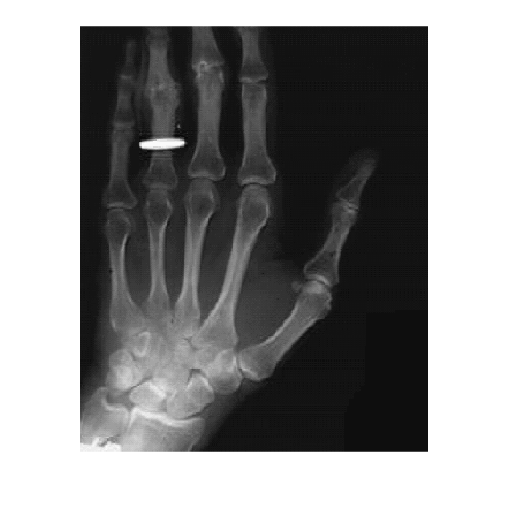

handxray_path = "handxray.tif";

handxray = imread(handxray_path);
figure;
subplot(1,1,1);
imshow(handxray);


hand_info = imfinfo(handxray_path);
hand_info

hand_info = struct with fields:
                     Filename: 'C:\Users\LENOVO\Desktop\PSUT\1st sem - Y4\Digital Image processing\images\handxray.tif'
                  FileModDate: '13-Nov-2023 10:40:19'
                     FileSize: 154210
                       Format: 'tif'
                FormatVersion: []
                        Width: 390
                       Height: 476
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 6715 12298 18149 24969 32065 39496 46288 53188 60393 67735 75353 82680 90157 97933 105709 112272 118684 124938 131423 137858 143733 149824]
              SamplesPerPixel: 1
                 RowsPerStrip: 21
              StripByteCounts: [6707 5583 5851 6820 70

Show a better contrast image

enhancedImg = histeq(handxray);

Displaying the difference in the image

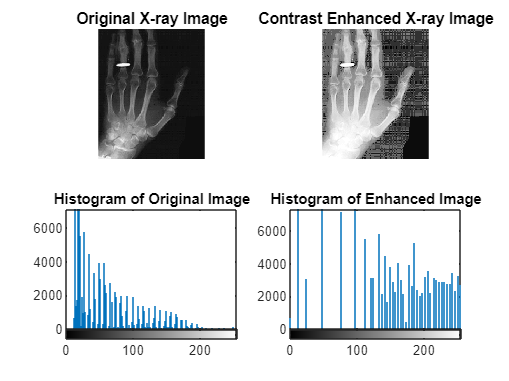

figure;
subplot(2, 2, 1);
imshow(handxray);
title('Original X-ray Image');

subplot(2, 2, 2);
imshow(enhancedImg);
title('Contrast Enhanced X-ray Image');

subplot(2, 2, 3);
imhist(handxray);
title('Histogram of Original Image');

subplot(2, 2, 4);
imhist(enhancedImg);
title('Histogram of Enhanced Image');

We can see that the original image is a normal xray image with no enhancment , after applying histeq() function , which shift the pixel values to be more uniform , since the original image has a lot of values consentrated between 0 and 200 , after adjusting , the values are shifted from 100 to 255 which resulted in a brighter image with more details and now we can see the edges of the hand and more defined bones.